export_images = true;

x = linspace(0,1);

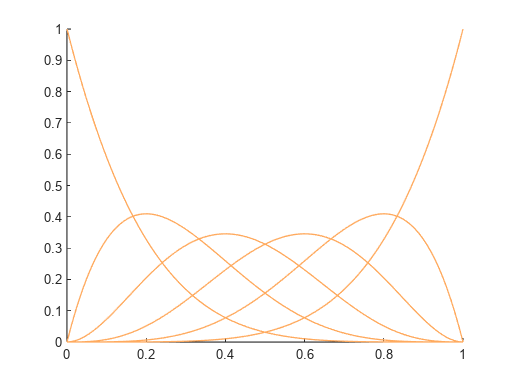

n = 5;

figure
hold on

for i = 0:n
    b = zeros(1,n+1);
    b(i+1) = 1;
    plot(x, polyval(bernstein2power(b),x), 'Color', '#FFAA5E', 'LineWidth', 1);
end
hold off

if export_images
    exportgraphics(gcf, 'decasteljau.pdf', 'ContentType', 'vector')
end

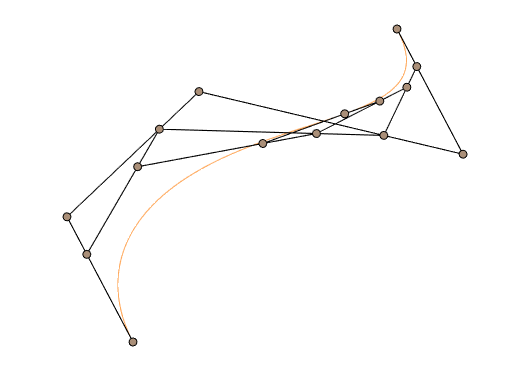

B = [0 0; -1 2; 1 4; 5 3; 4 5];
b = bezier(B, x);
t = 0.7;

figure
plot(b(:, 1), b(:, 2), 'Color', '#FFAA5E');
hold on

for i = 1:5
    plot(B(:, 1), B(:, 2), 'Color', 'black');
    hold on
    scatter(B(:, 1), B(:, 2), 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
    hold on

    newB = t * B(2:end, :) + (1-t) * B(1:end-1, :);
    B = newB;

end

grid off
set(gca,'visible','off')

if export_images
    exportgraphics(gcf, 'b1_example1.pdf', 'ContentType', 'vector')
end

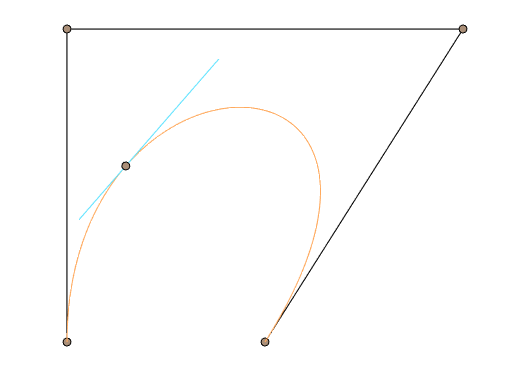

B = [0 0; 0 2; 8 2; 4 0];
b = bezier(B, x);

P = [19/16 9/8];
V = 3*[11/4 1];

norm_V = sqrt(V(1)^2 + V(2)^2);
V = V / norm_V;

vec = [P - V; P + 2 * V];

figure
plot(B(:, 1), B(:, 2), 'Color', 'black');
hold on
scatter(B(:, 1), B(:, 2), 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
plot(b(:, 1), b(:, 2), 'Color', '#FFAA5E');
hold on
plot(vec(:, 1), vec(:, 2), 'Color', '#5EE3FF');
hold on
scatter(P(:, 1), P(:, 2), 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');

grid off
set(gca,'visible','off')

if export_images
    exportgraphics(gcf, 'b1_example2.pdf', 'ContentType', 'vector')
end

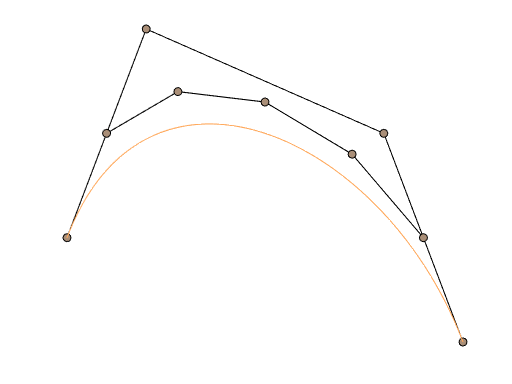

B = [0 0; 1 2; 4 1; 5 -1];
b = bezier(B, x);

B2 = [B(1, :); 0.5*(B(1, :) + B(2, :)); 0.2*(B(1, :) + 3*B(2, :) + B(3, :));
    0.05*(B(1, :) + 9*B(2, :) + 9*B(3, :) + B(4, :)); 0.2*(B(2, :) + 3*B(3, :) + B(4, :));
    0.5*(B(3, :) + B(4, :)); B(end, :)];

figure
plot(B(:, 1), B(:, 2), 'Color', 'black');
hold on
scatter(B(:, 1), B(:, 2), 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
plot(B2(:, 1), B2(:, 2), 'Color', 'black');
hold on
scatter(B2(:, 1), B2(:, 2), 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
plot(b(:, 1), b(:, 2), 'Color', '#FFAA5E');

grid off
set(gca,'visible','off')

if export_images
    exportgraphics(gcf, 'b1_example3.pdf', 'ContentType', 'vector')
end

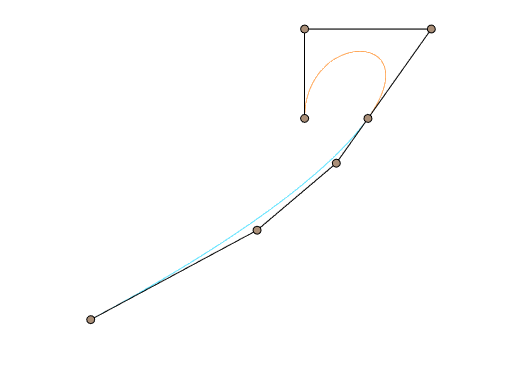

B = [0 0; 0 2; 8 2; 4 0];
C1 = [4 0; 2 -1; -3 -5/2; -27/2 -9/2];
C2 = [4 0; 2 -1; -3 -5/2; -4 0];

b = bezier(B, x);
c1 = bezier(C1, x);
c2 = bezier(C2, x);

figure
plot(b(:, 1), b(:, 2), 'Color', '#FFAA5E');
hold on
plot(c1(:, 1), c1(:, 2), 'Color', '#5EE3FF');
hold on
plot(B(:, 1), B(:, 2), 'Color', 'black');
hold on
scatter(B(:, 1), B(:, 2), 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
plot(C1(:, 1), C1(:, 2), 'Color', 'black');
hold on
scatter(C1(:, 1), C1(:, 2), 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');

grid off
set(gca,'visible','off')

if export_images
    exportgraphics(gcf, 'b1_example4.pdf', 'ContentType', 'vector')
end

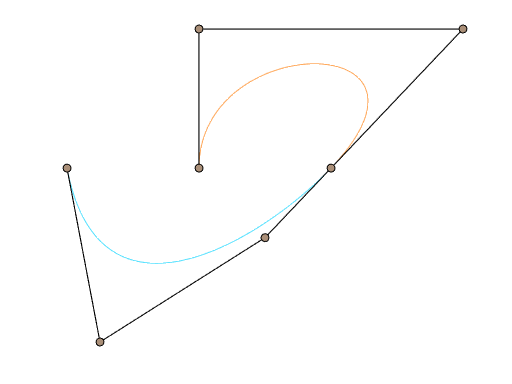


figure
plot(b(:, 1), b(:, 2), 'Color', '#FFAA5E');
hold on
plot(c2(:, 1), c2(:, 2), 'Color', '#5EE3FF');
hold on
plot(B(:, 1), B(:, 2), 'Color', 'black');
hold on
scatter(B(:, 1), B(:, 2), 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
plot(C2(:, 1), C2(:, 2), 'Color', 'black');
hold on
scatter(C2(:, 1), C2(:, 2), 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');

grid off
set(gca,'visible','off')

if export_images
    exportgraphics(gcf, 'b1_example5.pdf', 'ContentType', 'vector')
end